clc;
clear all;
close all;

% Parameters
Fs = 10;                     % Sampling frequency (Hz)
speed = 15;                  % Speed in mm/s
Amplitude = 100;             % Amplitude of sine wave (mm)
period_mm = 200;             % Spatial period (mm)
rectangle_width = 400;      % Width of the rectangle (mm)

% Initial zero segment
T_zero = 5;                 % Duration in seconds
t_zero = (0:1/Fs:T_zero-1/Fs)';
x_zero = zeros(size(t_zero));
y_zero = zeros(size(t_zero));

% Transition to (-160, -50)172.16.0.3

x_start = 0;
y_start = 0;
x_end = -160;
y_end = -50;


dx = x_end - x_start;
dy = y_end - y_start;
distance = sqrt(dx^2 + dy^2);         % Total distance to move
T_transition = distance / speed;     % Time to complete transition
t_transition = (0:1/Fs:T_transition)';
x_transition = x_start + (dx / distance) * speed * t_transition;
y_transition = y_start + (dy / distance) * speed * t_transition;

% Sinusoidal wave after transition
T_wave = rectangle_width / speed;    
t_wave = (0:1/Fs:T_wave)';
spatial_freq = 1 / period_mm;
x_wave = x_end - speed * t_wave;
y_wave = y_end - Amplitude * sin(2 * pi * spatial_freq * (x_wave - x_end));

% Concatenate all segments
t = [t_zero;
     t_zero(end) + (1/Fs) + t_transition;
     t_zero(end) + (1/Fs) + t_transition(end) + (1/Fs) + t_wave];

x = [x_zero;
     x_transition;
     x_wave];

y = [y_zero;
     y_transition;
     y_wave];

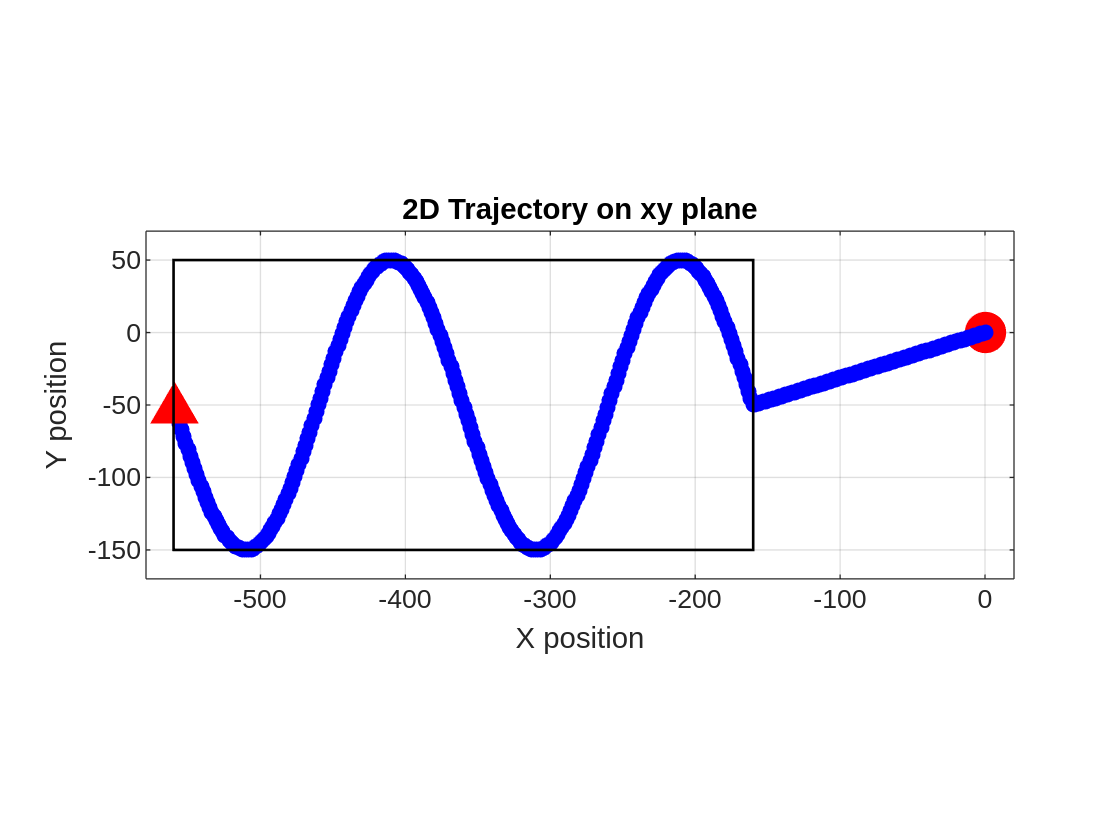

% Plot the 2D trajectory
figure;

% Plot the first point as a red circle
plot(x(1), y(1), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 15);
hold on;

% Plot the middle points (excluding first and last) in blue
if length(x) > 2
    plot(x(2:end-1), y(2:end-1), '-o', 'LineWidth', 2, 'Color', 'b', ...
         'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b', 'MarkerSize', 4);
end

% Plot the last point as a red triangle
plot(x(end), y(end), 'r^', 'MarkerFaceColor', 'r', 'MarkerSize', 15);

% Draw rectangle with corners at (-160, 50) and (-560, -150)
x_corner = -560;
y_corner = -150;
width = -160 - x_corner;     % 400
height = 50 - y_corner;      % 200
rectangle('Position', [x_corner, y_corner, width, height], ...
          'EdgeColor', 'k', 'LineWidth', 1); % 'k' = black

grid on;
xlabel('X position');
ylabel('Y position');
title('2D Trajectory on xy plane');
axis equal;
xlim([min(x-20) max(x+20)]);
ylim([min(y-20) max(y+20)]);

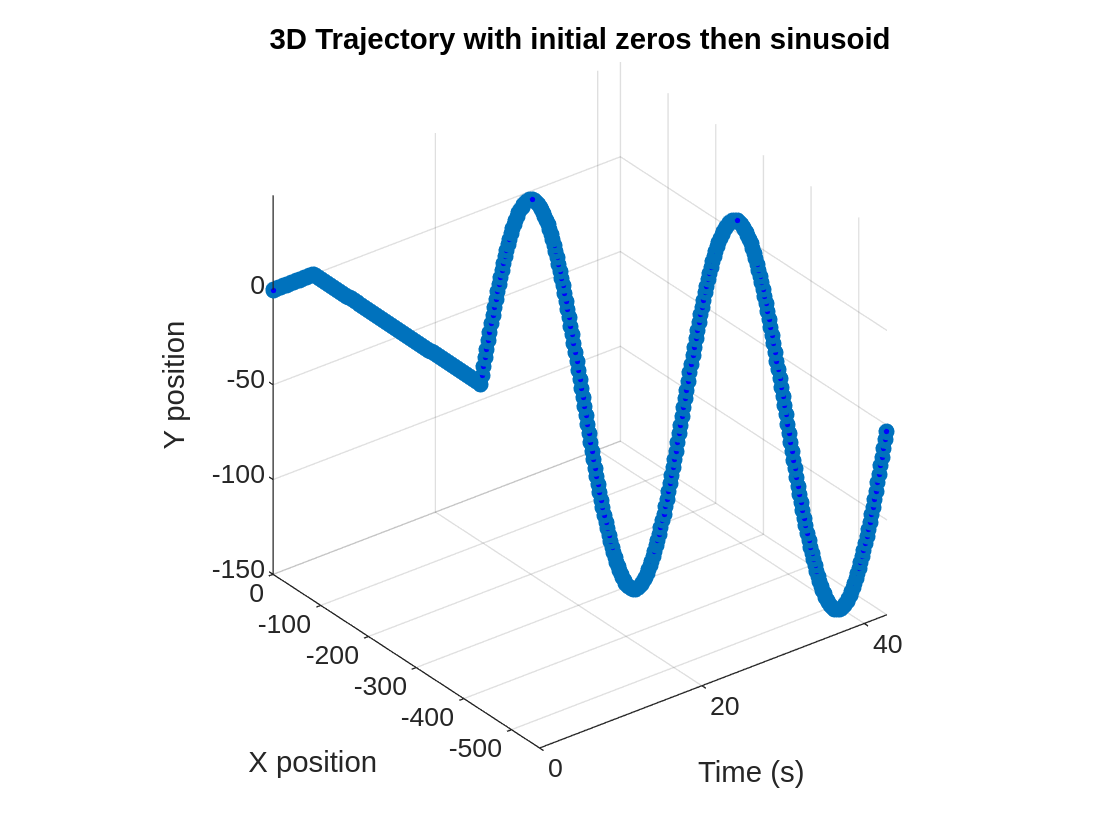

% Plot the combined 3D trajectory
figure;
plot3(t, x, y, '-o', 'LineWidth', 2, 'MarkerSize', 4, 'MarkerFaceColor', 'b')
grid on;
xlabel('Time (s)');
ylabel('X position');
zlabel('Y position');
title('3D Trajectory with initial zeros then sinusoid');
xlim([min(t) max(t)]);
ylim([min(x) max(x)]);
zlim([min(y) max(y)]);
axis vis3d;

Save the data

temp=x;
x=-y;
y=temp;

% Save time and positions as separate variables
save('sinusoid_trajectory.mat', 't', 'x', 'y');

Pixel calculation

diagonal=sqrt(3840^2+2160^2);
ppi=diagonal/13;
p_mm=ppi/25.4

p_mm = 13.3429

mm_p=1/p_mm

mm_p = 0.0749